## Module one project 11

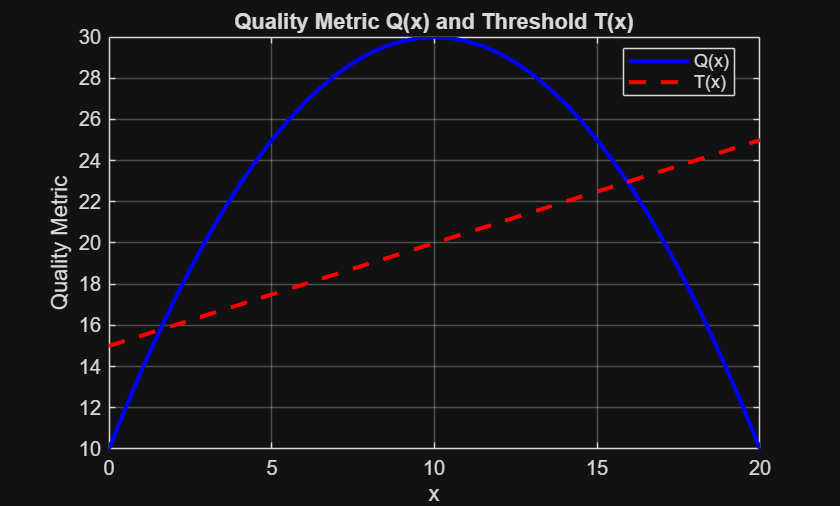

%% Project 11: Inspection Threshold Detection (Intersection + Logic)
clear; clc; close all;

%% -------------------------------------------------------------
% 1. Define Q(x) as a quadratic model on x = 0 : 0.5 : 20
% -------------------------------------------------------------
x = 0:0.5:20;

% Quadratic quality metric (example: concave-down performance curve)
Q = -0.2*x.^2 + 4*x + 10;

%% -------------------------------------------------------------
% 2. Define a linear threshold T(x)
% -------------------------------------------------------------
T = 0.5*x + 15;     % linear threshold line

%% -------------------------------------------------------------
% 3. Plot Q(x) and T(x)
% -------------------------------------------------------------
figure;
plot(x, Q, 'b', 'LineWidth', 2); hold on;
plot(x, T, 'r--', 'LineWidth', 2);
grid on;

xlabel('x');
ylabel('Quality Metric');
title('Quality Metric Q(x) and Threshold T(x)');
legend('Q(x)', 'T(x)', 'Location', 'best');


%% -------------------------------------------------------------
% 4. Find where Q(x) >= T(x)
% -------------------------------------------------------------
passMask = Q >= T;     % logical mask of pass/fail

% Identify continuous pass intervals
d = diff([0 passMask 0]);   % detect rising/falling edges
startIdx = find(d == 1);
endIdx   = find(d == -1) - 1;

% Build interval list
passIntervals = [];
for i = 1:length(startIdx)
    x_start = x(startIdx(i));
    x_end   = x(endIdx(i));
    passIntervals = [passIntervals; x_start x_end];
end

%% Display pass/fail intervals
fprintf('Pass intervals (Q(x) >= T(x)):\n');

Pass intervals (Q(x) >= T(x)):


if isempty(passIntervals)
    fprintf('No intervals satisfy Q(x) >= T(x).\n');
else
    for i = 1:size(passIntervals,1)
        fprintf('  Interval %d: x = %.2f to x = %.2f\n', ...
            i, passIntervals(i,1), passIntervals(i,2));
    end
end

  Interval 1: x = 2.00 to x = 15.50



%% -------------------------------------------------------------
% 5. Summary (4–6 sentences)
% -------------------------------------------------------------
fprintf('\nSummary:\n');


Summary:


fprintf(['The quadratic quality metric Q(x) increases initially, reaches a peak,\n' ...
         'and then decreases as x becomes large. The linear threshold T(x)\n' ...
         'grows steadily with x, creating one or more intersection points.\n' ...
         'Where Q(x) lies above T(x), the system passes inspection; otherwise it fails.\n' ...
         'Based on the computed intervals, the pass regions occur where Q(x)\n' ...
         'remains higher than the threshold line.\n']);

The quadratic quality metric Q(x) increases initially, reaches a peak,
and then decreases as x becomes large. The linear threshold T(x)
grows steadily with x, creating one or more intersection points.
Where Q(x) lies above T(x), the system passes inspection; otherwise it fails.
Based on the computed intervals, the pass regions occur where Q(x)
remains higher than the threshold line.
